# **MSc Translation Neuroscience Module 3 - Workshop 1**

Welcome to your first workshop of Module 3!

In this workshop, we will teach you in more detail the essentials of how to code in MATLAB, with many examples along the way.

This workshop is going to set the basis for the rest of the module, since all the following work will be done on MATLAB. It is therefore essential that you understand the key concepts presented here, and that you give it your best!

Coding is a unique practice that can take some time to get used to, so don't get discouraged if you are struggling! You can always rely on your GTAs, who are here to guide you in this learning process. Don't hesitate to ask any questions, even if you think it may be stupid or not worth our time, our job is to help you progress and understand the material, so fire away!

Whilst day 1 of the module is dedicated to this workshop, we encourage you to read through it again during your revision time, and to keep it open throughout the module as you will probably need a refresher on different programming concepts!

The workshop is divided into different topics. Each topic has different sub-topics, and you should find one or more exercises in each of these. It is essential that you attempt and understand the exercises, as programming is a very hands-on practice, that needs repetition to get used to it. The solutions to these exercises will be given on day 2, to ensure that you attempt them to the fullest.

Best of luck!

# 1. MATLAB Interface and Outputs

### 1.1 Graphical User Interface (GUI)

For you to use MATLAB, it is important to understand the Graphical User Interface, or GUI.

The GUI is composed of five main components:

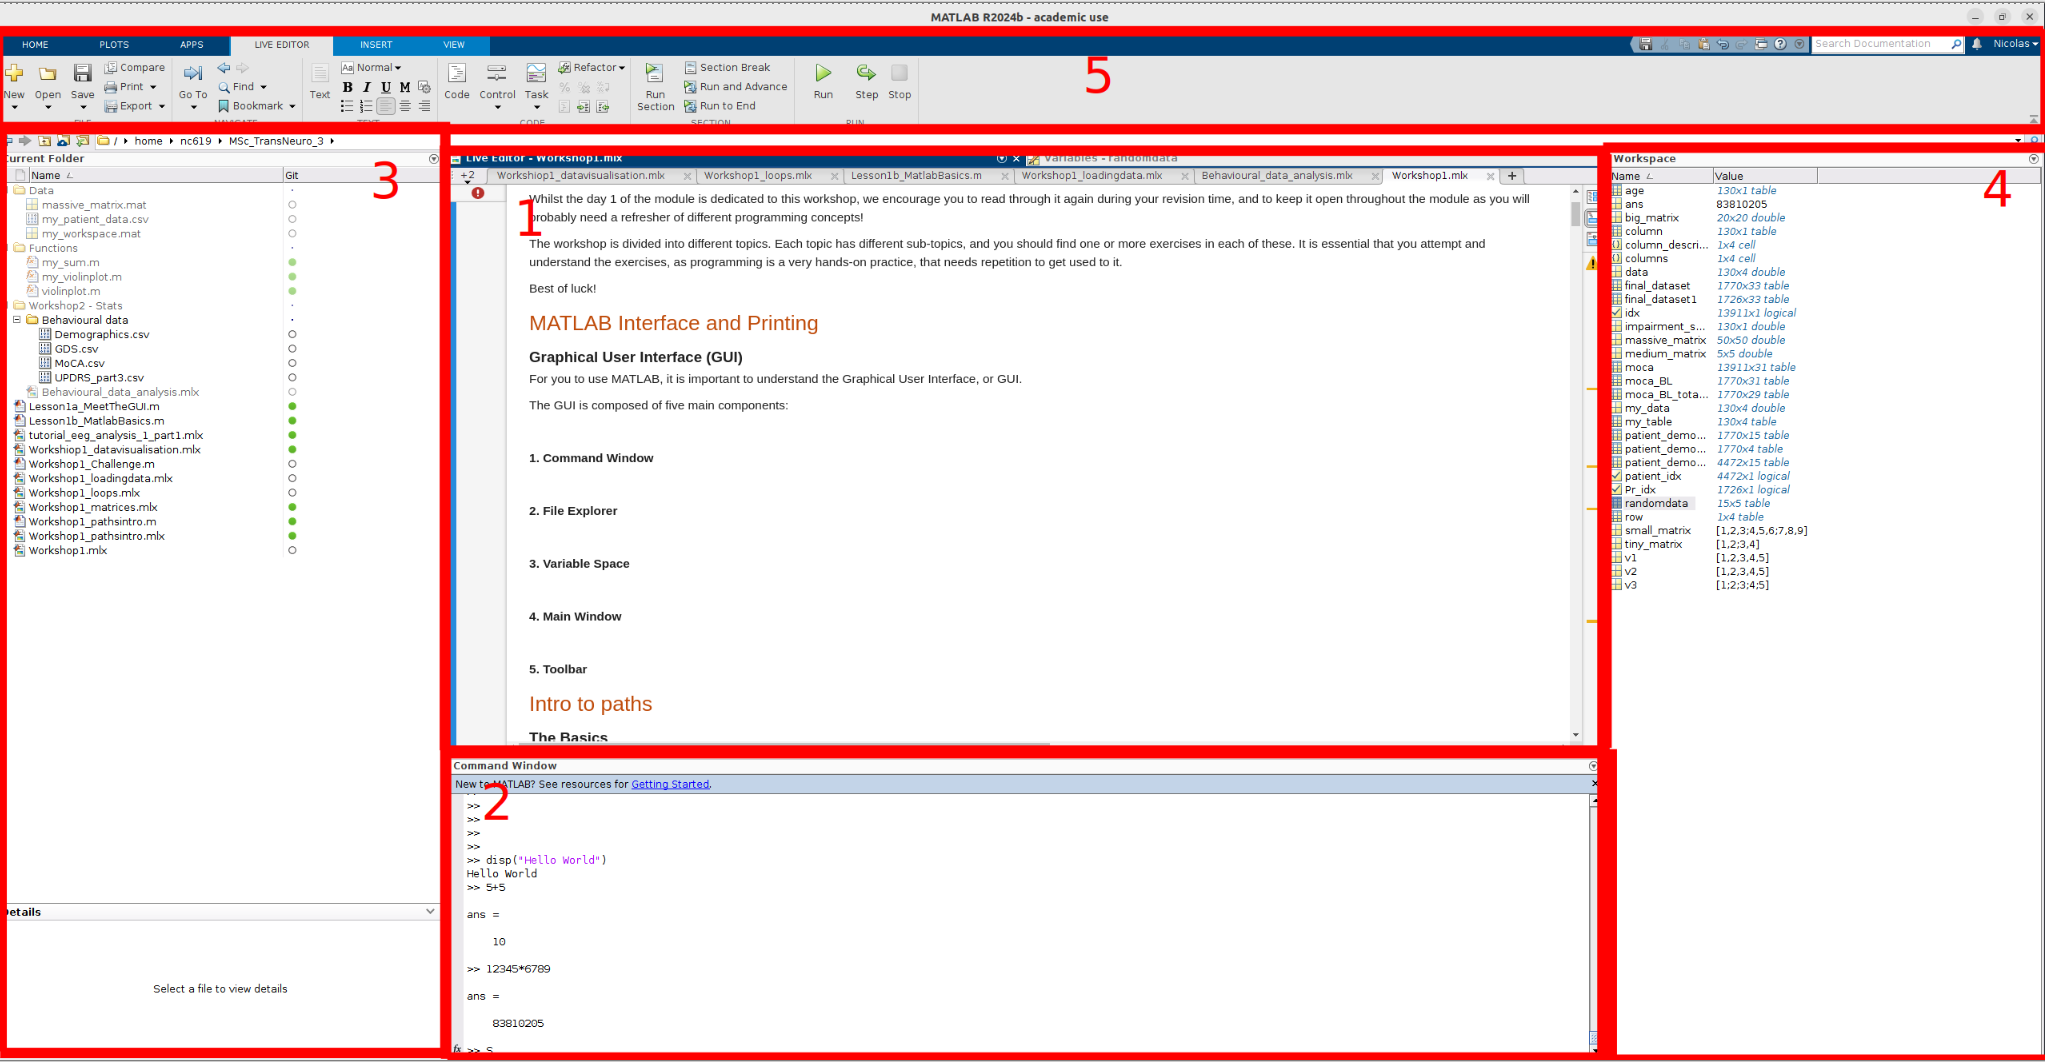

**1. Main Window (middle)**

The main window is where you will see the currently opened file. Usually, you will have your main code open here, in this case you have the workshop live script open.

**2. Command Window (bottom)**

The command window is a terminal where you can write commands one by one and get their output. It's useful for quick calculations, or testing things out without needing to create a script for it.

**3. File Explorer (left)**

The file explorer shows you your current location in your computer's storage, and shows a tree view of the available files and folders.

**4. Variable Space (right)**

The variable space shows all the variables that are currently loaded into MATLAB. This is one of MATLAB's most useful features, as you can see the dimensions (size) of a variable, and you can double click on it to see a detailed view of it. Yours should be empty right now.

**5. Toolbar (top)**

The toolbar allows you to access different MATLAB functionalities, which are useful to edit and run scripts, amongst other things. You won't be using the toolbar too much.

### 1.2 Outputs

Now that we got that out of our way, let's do some programming!

You are currently working with a live script, which has text mixed with code. Try running the code box below using the `Ctrl + Enter` (windows) or `Cmd + Enter `(mac/linux) shortcut:

disp("Hello World!")

Hello World!


It printed `Hello World!` to the script!

This is because we used the function `disp()` which prints (outputs) whatever you put in it between the parentheses.

Another way to handle printing of things in MATLAB, is by using the semicolon.

By default MATLAB prints the output of statements (run using `Ctrl/Cmd+Enter`):

a = 5

a = 5

"Hello"

ans = "Hello"

-10

ans = -10

To avoid this, we can use the semicolon character `";".`

For example:

a = 5;
"Hello";
-10;

Didn't output anything.

This is very useful to keep our scripts clean and only output what is necessary. Also, when dealing with large amounts of data, it would be ugly and extremely slow to print the output of every operation you do with a matrix that has for example 100000 elements. So unless you want to explicitly see the output of an operation, you should always include the semicolon character `";"` at the end of your lines

# 2. Intro to paths

### 2.1 The Basics

Most programming languages and software, including MATLAB, use the concept of paths.

You have most likely encountered paths before, when looking for something in your directory. These can look something of the form:

`"C:\Users\nicol\MSc_TransNeuro_Mod3"`

Paths indicate the path your computer has to follow, in order to find a desired folder or file in your memory. In MATLAB, you can see your current path at the top of the user interface:

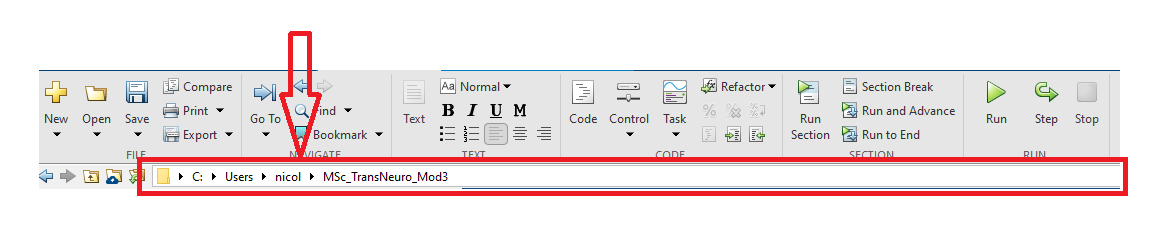

This allows MATLAB to know where to look for files.

### 2. 2 Syntax of Paths

Paths have a particular syntax, for both Mac and Windows, you can use 

"/";

As the separator character between folders

**2.2.1 WINDOWS: **

In Windows paths start with your hard drive, which is given a letter, most commonly starting at *C: *

A common Windows path can look like: `"C:\Users\nicol\MSc_TransNeuro_Mod3"`

NOTE: Here the path separator is the backslash `"\"` instead of the normal slash `"/"`. This is because windows uses the backslash as default, but the normal slash still works in MATLAB.

**2.2.2 MAC/LINUX: **

In UNIX-based systems (MacOS or Linux), the paths start with a slash character `"/"`, followed by a series of folders.

An example of a common UNIX path can look like: `"/home/nicol/MSC_TransNeuro_Mod3".`

**2.2.3 Relative paths:**

You might have noted that in the previous examples, paths went all the way from the starting point of your memory, to the desired location. However, to make writing easier, you can use relative paths, which only indicate the path from your current location to your destination.

For example, if you wanted to access the "MyFolder`" `folder inside `"Functions"`, you could just type `"Functions/MyFolder"`

Relative paths also allow you to go backwards, by using the `".."` string. 

For example, accessing `"Functions/.."` is the same as accessing the current folder.

### 2.3 Using paths in MATLAB

If MATLAB only used the path that you currently have open in the GUI's search bar at the top to look for files, it would be limited in use-cases.

To solve this, you use matlab's addpath function, to tell it where to look.

For example, if you try to run the following code:

my_sum(1,3) % This won't work

Unrecognized function or variable 'my_sum'.

You will receive an error message saying this function was not found in the path. This is because MATLAB does not have any function called `"my_sum"` by default.

To tell MATLAB where to find it, we can add the Functions folder to the path, and try again:

addpath("Functions") % Here we are using the relative path
my_sum(1,3) % This will work

You are amazing!
... and the sum is 4
Have a great day!


You can always undo this by using the `rmpath()` command:

rmpath("Functions")
my_sum(1,3) % This won't work again

You can also check your current paths by using the following command, although the output might be quite long:

disp(path)

/home/nc619/MSc_TransNeuro_3/Functions:/home/nc619/MSc_TransNeuro_3/Workshop2 - Stats/Behavioural data:/home/nc619/Documents/MATLAB:/tmp/Editor_rzyjk:/usr/local/MATLAB/R2024b/toolbox/matlab/addon_enable_disable_management/matlab:/usr/local/MATLAB/R2024b/toolbox/matlab/addon_updates/matlab:/usr/local/MATLAB/R2024b/toolbox/matlab/addons:/usr/local/MATLAB/R2024b/toolbox/matlab/addons/cef:/usr/local/MATLAB/R2024b/toolbox/matlab/addons/fileexchange:/usr/local/MATLAB/R2024b/toolbox/matlab/addons/supportpackages:/usr/local/MATLAB/R2024b/toolbox/matlab/addons_common/matlab:/usr/local/MATLAB/R2024b/toolbox/matlab/addons_desktop_registration:/usr/local/MATLAB/R2024b/toolbox/matlab/addons_install_location/matlab:/usr/local/MATLAB/R2024b/toolbox/matlab/addons_product:/usr/local/MATLAB/R2024b/toolbox/matlab/addons_product_support/matlab:/usr/local/MATLAB/R2024b/toolbox/matlab/addons_registry/matlab:/usr/local/MATLAB/R2024b/toolbox/matlab/addons_sidepanel/matlab:/usr/local/MATLAB/R2024b/toolbox/matl

# 3. Arrays: Vectors & Matrices

### 3.1 Arrays

MATLAB is a programming language that is optimised to work well with objects called arrays. Arrays are an n-dimensional data structures that contain elements (usually numbers). Each element inside an array is ordered and can be accessed with indices. For example, if I wanted to access the first element of a 4-D array, my indices would be [1, 1, 1, 1].

To start with, we will work with 1-D and 2-D arrays, also known as **vectors **and **matrices **respectively

### 3.2 Vectors

**3.2.1 What is a vector?**

A vector is a 1-D series of ordered variables, most commonly scalars.

**3.2.3 Vector syntax**

In MATLAB, vectors are defined with square brackets `"[]"`, and the elements of a vector are separated by a comma `","`, a space `" "`, or a semicolon `";"`

For example:

v1 = [1,2,3,4,5] % Row vector

v1 =      1     2     3     4     5


v2 = [1 2 3 4 5] % Row vector

v2 =      1     2     3     4     5


v3 = [1; 2; 3; 4; 5] % Column vector

v3 =      1
     2
     3
     4
     5


You might have noted on the output that `v1` and `v2` are **row vectors**, meaning they are of size `1 x N` and that v3 is a **column vector,** meaning it is of size `N x 1``.` 

This is because MATLAB uses the comma `","` character to separate between **columns**, and uses the semicolon `";"` character to separate between **rows**.

**Try it yourself!**

*Exercise 3.1*

Use the code box below to have a try at **instantiating** some vectors, and check whether the output matches what you expected. If you are lacking inspiration, you could write two vectors, one row vector having 6 odd numbers and column vector having 6 even numbers.

v4 = [1,3,5,7,9,11]

v4 =      1     3     5     7     9    11


v5 = [2;4;6;8;10;12] 

v5 =      2
     4
     6
     8
    10
    12


### 3.3 Matrices

**3.3.1 Matrices in MATLAB**

**Vectors and matrices** are **defined **in the **same way **in MATLAB, where a vector is just a 2D matrix that has one of its dimensions equal to 1.

To instantiate a matrix, we therefore use the same syntax:

m1 = [1,2;3,4] % 2 x 2 matrix

m1 =      1     2
     3     4


m2 = [1,2,3;4,5,6;7,8,9] % 3 x 3 matrix

m2 =      1     2     3
     4     5     6
     7     8     9


m3 = eye(4) % 4 x 4 identity matrix

m3 =      1     0     0     0
     0     1     0     0
     0     0     1     0
     0     0     0     1


m4 = randn(3,3) % 3 x 3 random matrix

m4 =     0.5377    0.8622   -0.4336
    1.8339    0.3188    0.3426
   -2.2588   -1.3077    3.5784


m5 = ones(5,3) % 5 x 3 ones matrix

m5 =      1     1     1
     1     1     1
     1     1     1
     1     1     1
     1     1     1


m6 = [1,2,3;4,5,6] % 2 x 3 matrix

m6 =      1     2     3
     4     5     6


**Check the output **of every matrix one by one. If you don't want to use the printed output, you can also do it by looking at the **variable space** (usually located on the right-side of the GUI) and double clicking on them.

Make sure that you **understand** the **syntax** of matrix initialisation by looking at whether the outputs match your expectations.

**3.3.2 Basic Matrix Operations**

With matrices, you can do many operations:

m1 * 2 % Scalar multiplication

ans =      2     4
     6     8


m1 / 2 % Scalar division

ans =     0.5000    1.0000
    1.5000    2.0000


m1 + 3 % Scalar addition

ans =      4     5
     6     7


m1 ^ 2 % Power (only works with square matrices)

ans =      7    10
    15    22


m5 * m2 % Matrix multiplication

ans =     12    15    18
    12    15    18
    12    15    18
    12    15    18
    12    15    18


m2 + m4 % Matrix addition (element-wise)

ans =     1.5377    2.8622    2.5664
    5.8339    5.3188    6.3426
    4.7412    6.6923   12.5784


m2 .* m4 % Element-wise matrix multiplication

ans =     0.5377    1.7243   -1.3008
    7.3355    1.5938    2.0557
  -15.8119  -10.4615   32.2056


m2 ./ m4 % Element-wise matrix division

ans =     1.8599    2.3197   -6.9189
    2.1812   15.6855   17.5119
   -3.0989   -6.1177    2.5151


1 ./ m1 % Element-wise inverse

ans =     1.0000    0.5000
    0.3333    0.2500


Of course, if the dimensions are incorrect, this will give an error.

For example

m5 * m2 % this will work ( 5x3 * 3x3 )

ans =     12    15    18
    12    15    18
    12    15    18
    12    15    18
    12    15    18


% NOTE for the curious minds: Try-Catch blocks are a MATLAB syntax
% that allows to handle errors, they can be interpreted as:
% if not error:
%   statement 1
% else:
%   statement 2

try
    m2 * m5 % this will not work ( 3x3 * 5x3)
catch
    disp("ERROR: Incorrect dimensions for matrix multiplication. Check that the number of columns in the first matrix matches the number of rows in the second matrix. To operate on each element of the matrix individually, use TIMES (.*) for elementwise multiplication.")
end

ERROR: Incorrect dimensions for matrix multiplication. Check that the number of columns in the first matrix matches the number of rows in the second matrix. To operate on each element of the matrix individually, use TIMES (.*) for elementwise multiplication.


*Exercise 3.2*

Instantiate two 2 x 2 matrices of your choice, and calculate by hand the result of their product, and element-wise product. Then, write some code to check your results 

(Reminder of matrix multiplication if needed: [https://www.mathsisfun.com/algebra/matrix-multiplying.html)](https://www.mathsisfun.com/algebra/matrix-multiplying.html)) 

**3.3.3 Other Matrix Operations**

Other matrix operations can be done in MATLAB, here are a few examples:

m6' % Transpose (swaps the rows and columns of a matrix)

ans =      1     4
     2     5
     3     6


transpose(m6) % Same thing, different notation

ans =      1     4
     2     5
     3     6


det(m1) % Determinant of a matrix (only works on square matrices)

ans = -2

inv(m1) % Inverse of a matrix (only works on square matrices)

ans =    -2.0000    1.0000
    1.5000   -0.5000


eig(m1) % Returns eigenvalues of a matrix (only works on square matrices)

ans =    -0.3723
    5.3723


*Exercise 3.3*

We saw before that `m2 * m5` gave an error. Use a matrix operation to **fix this error**, whilst **keeping **`m2`** as the first term **of the product (the output should be of the form  "`m2 * transform(m5)")`.

m2*m5'

ans =      6     6     6     6     6
    15    15    15    15    15
    24    24    24    24    24


### 3.4 Indexing

**3.5.1 Basic Indexing**

**Indexing** refers to the **accessing of specific elements** within an array.

In MATLAB, indexing starts at 1, and is detailed by using brackets "`()"`. The keyword "`end"` can be used to access the last element of an array.

For example:

v1 % vector

v1 =      1     2     3     4     5


v1(1) % first element of the vector

ans = 1

v1(end) % last element of the vector

ans = 5

For matrices, the element of each dimension is separate by a comma.

For example:

m2 % matrix

m2 =      1     2     3
     4     5     6
     7     8     9


m2(1,1) % first row and first column element

ans = 1

m2(1,2) % first row and second column element

ans = 2

m2(end,end) % last row and last column element

ans = 9

*Exercise 3.4*

Use indices to extract the number 6 from m2

num5 = m2(2,3) %WRITE YOUR CODE HERE

num5 = 6


if num5 == 6
    disp("Well done")
else
    disp("Try again")
end

Well done


**3.5.2 Array indexing**

When **indexing**, you can **access multiple elements at once** using arrays of indices.

For example, if you wished to access the second and third column of the first row of `m2`, this could be done with array indexing:

sub_m2 = m2(1,[2,3])

sub_m2 =      2     3


*Exercise 3.5*

Use array indexing to retrieve the following information:

m6([1,2],1) % Elements equal to 1 and 4 from m6 (Hint: look at m6 again to see the indices where elements are equal to 1 and 4)

ans =      1
     4


m3([1,2],[3,4]) % The 3rd and 4th columns of the 1st and 2nd rows of m3

ans =      0     0
     0     0


m3([1,2,3,4],[1,2,3]) % All elements except the last column of m3

ans =      1     0     0
     0     1     0
     0     0     1
     0     0     0


**3.5.3 Slicing**

**Writing out** all the **indices** can be a **lengthy** process, to make this easier and cleaner to read, **we use slicing**.

Slicing is indicated by the semicolon character `":"` to generate arrays in the following way:

`start:step:stop`

**If **`step`** overshoots** and doesn't land on `stop, `the previous biggest element is taken as the last one of the sequence (see `sl_5` in the example below)

**If **`step=1`, this doesn't need to be explicitly written out, and slicing can be written as 

`start:stop`

The semicolon character can also be used by itself, in which case it indicates all elements of a dimension, in other terms

`: <=> 1:end`

Below are a few examples to generate arrays using slicing:

sl_1 = 1:10 % Numbers from 1 to 10

sl_1 =      1     2     3     4     5     6     7     8     9    10



sl_2 = 0:10:100 % Multiples of 10 from 0 to 100

sl_2 =      0    10    20    30    40    50    60    70    80    90   100



sl_3 = 0:0.1:1 % First decimal points from 0 to 1

sl_3 =          0    0.1000    0.2000    0.3000    0.4000    0.5000    0.6000    0.7000    0.8000    0.9000    1.0000



sl_4 = 10:-1:0 % Numbers from 10 to 1 (decreasing)

sl_4 =     10     9     8     7     6     5     4     3     2     1     0



sl_5 = 1:3:5 % If one of the steps doesn't finish at stop, the biggest element before stop is the last one

sl_5 =      1     4


*Exercise 3.6*

Find three ways to generate an empty array using slicing

% NOTE: You are not required to use the same start/stop/step for the different
% scenarios

empty_1 = 0:-1 % Should look something like start:stop


empty_1 =

  1×0 empty double row vector



empty_2 = 10:2:0 % Should look something like start:step:stop


empty_2 =

  1×0 empty double row vector



empty_3 = 0:-1:10 % Should look something like start:-step:stop


empty_3 =

  1×0 empty double row vector



*Exercise 3.7*

Use slicing to generate the following arrays:

slice1 = -3:1/3:3 % The ticks of an x-axis going from -3 to 3 with ticks at every 1/3

slice1 =    -3.0000   -2.6667   -2.3333   -2.0000   -1.6667   -1.3333   -1.0000   -0.6667   -0.3333         0    0.3333    0.6667    1.0000    1.3333    1.6667    2.0000    2.3333    2.6667    3.0000


slice2 = 1:-0.2:0 % The height of different steps of a staircase starting from the top (starts at 1m, every step is 20cm, and the ground is at 0m)

slice2 =     1.0000    0.8000    0.6000    0.4000    0.2000         0


If we combine array indexing with slicing, we get an elegant way to access data inside matrices.

For example, you can use slicing to retrieve elements at the odd indices of a vector

v1

v1 =      1     2     3     4     5


odd_elements = v1(1:2:end)

odd_elements =      1     3     5


*Exercise 3.8*

Use slicing to initalise a vector going from 0 to 20 in steps of 2, and then use slicing to reverse it

v6 = 0:2:20 % Vector

v6 =      0     2     4     6     8    10    12    14    16    18    20


v6_reverse = v6(end:-1:1) % Reverse the vector

v6_reverse =     20    18    16    14    12    10     8     6     4     2     0


*Exercise 3.9*

Below is a 10x10 sorted matrix that has all numbers from 1 to 100 (first row is numbers from 1-10, second row is numbers from 11-20, etc...)

m_slice = reshape((1:100),[10,10])' %%% DON'T CHANGE THIS LINE %%%

m_slice =      1     2     3     4     5     6     7     8     9    10
    11    12    13    14    15    16    17    18    19    20
    21    22    23    24    25    26    27    28    29    30
    31    32    33    34    35    36    37    38    39    40
    41    42    43    44    45    46    47    48    49    50
    51    52    53    54    55    56    57    58    59    60
    61    62    63    64    65    66    67    68    69    70
    71    72    73    74    75    76    77    78    79    80
    81    82    83    84    85    86    87    88    89    90
    91    92    93    94    95    96    97    98    99   100


Use slicing to complete the following tasks on `m_slice`:

first_row = m_slice(1,:) % Retrieve the first row of the matrix

first_row =      1     2     3     4     5     6     7     8     9    10


third_column = m_slice(:,3) % Retrive the third column of the matrix 

third_column =      3
    13
    23
    33
    43
    53
    63
    73
    83
    93


odd_numbers = m_slice(:,1:2:end) % Retrieve all odd numbers

odd_numbers =      1     3     5     7     9
    11    13    15    17    19
    21    23    25    27    29
    31    33    35    37    39
    41    43    45    47    49
    51    53    55    57    59
    61    63    65    67    69
    71    73    75    77    79
    81    83    85    87    89
    91    93    95    97    99


even_numbers = m_slice(:,2:2:end) % Retrieve all even numbers

even_numbers =      2     4     6     8    10
    12    14    16    18    20
    22    24    26    28    30
    32    34    36    38    40
    42    44    46    48    50
    52    54    56    58    60
    62    64    66    68    70
    72    74    76    78    80
    82    84    86    88    90
    92    94    96    98   100


numbers_10 = m_slice(:,end) % Retrieve all numbers divisible by 10

numbers_10 =     10
    20
    30
    40
    50
    60
    70
    80
    90
   100


**3.5.4 Conditional Indexing**

As you will see throughout the course, we often have to deal with very big arrays (millions of elements), which makes it hard to know which indices to use. With **conditional indexing**, instead of manually checking each element, we create a logical array that is **true** for elements that meet the condition and **false** for those that do not.

This technique is useful when working with large datasets or when you **need to perform operations based on specific criteria**, such as values greater than a certain threshold.

Conditional indexing works by applying a condition directly to the array. For example:

A = [1, 10, 12; 3 9 2]

A =      1    10    12
     3     9     2


cond = A > 5 % Creates a logical array where each element is tested

cond = 2×3 logical array
   0   1   1
   0   1   0


Here `cond `will be: `[0, 1, 1; 0, 1, 0]` where `0` indicates `false` and `1` indicates `true.`

A(cond) % All elements bigger than 5

ans =     10
     9
    12


In order to find where these outliers are, you can use MATLAB's built-in `find` function.

[rows, columns] = find(A>5) % finds each element in which the condition is met

rows =      1
     2
     1


columns =      2
     2
     3


indices = [rows, columns] % concatenate the outputs since find() returns them separately

indices =      1     2
     2     2
     1     3


example_index = indices(1,:) % (1,2) is an example index

example_index =      1     2


*Exercise 3.10*

Below is a matrix that has 1 million elements. 

big_matrix = randi([0,100],1000)

big_matrix =     97    42    59    12     0    59    63    32    93    27    32    28    78    63     8    79    35    17    61    84    53    78    10     1    45    33     9    95    41    43    96    95    23     3    42    97    95    53    19     3    85    27    65    30    33    58    43    67    88     4
    15    18    16    99    83    18    29    29    62    30     5     7    57    50    31    99    85    91    89    37    16    32    98    77     4    70    99    15     9     9    30    68    71    39    47    31     7    64     7    63    59    19    47   100    96    40    54    92    12    47
    98    73    84    50    77     7    62    50    69     0    14    73     2    79    86    69    54    67    52    12    36    61    41    72    61    38    75    67    70    30    73    22    77    74    31    22    34    35    75    78    78    36    50    82    91    16    91    51    10    13
    96    37    16     2   100    15     4    18    23    23    73    34    51    71

big_matrix(randi([1,1000],1), randi([1,1000],[3,1])) = randi([-100,-1],[1,3])

big_matrix =     97    42    59    12     0    59    63    32    93    27    32    28    78    63     8    79    35    17    61    84    53    78    10     1    45    33     9    95    41    43    96    95    23     3    42    97    95    53    19     3    85    27    65    30    33    58    43    67    88     4
    15    18    16    99    83    18    29    29    62    30     5     7    57    50    31    99    85    91    89    37    16    32    98    77     4    70    99    15     9     9    30    68    71    39    47    31     7    64     7    63    59    19    47   100    96    40    54    92    12    47
    98    73    84    50    77     7    62    50    69     0    14    73     2    79    86    69    54    67    52    12    36    61    41    72    61    38    75    67    70    30    73    22    77    74    31    22    34    35    75    78    78    36    50    82    91    16    91    51    10    13
    96    37    16     2   100    15     4    18    23    23    73    34    51    71

All elements are positive integers, except for 3 hidden elements which are negative numbers. Find what they are.

outliers = [] % 3 numbers inside big_matrix that are below 0


outliers =

     []



Now using MATLAB's `find` function, find the indices for each of these elements

% ... code ...
final_indices1 = []


final_indices1 =

     []



final_indices2 = []


final_indices2 =

     []



final_indices3 = []


final_indices3 =

     []




% NOTE: feel free to plug these indices back into big_matrix to 
% check whether you got the correct one. You should get negative
% numbers if you did the exercise correctly.

### **3.5 Min-Max**

**3.6.1 Intro to min & max functions**

Two very **useful matlab functions** are `min `and `max`. 

As the names indicate these functions allow to **retrieve the minimum and maximum of an array**.

For example:

v1_max = max(v1)

Unrecognized function or variable 'i_m1_max'.

v1_min = min(v1)

*Exercise 3.11*

Open m1 in the variable viewer and take a note of what you see as the maximum and minimum

Then, write some code to extract the maximum and minimum of m1, and check whether this is the result you expected

m1_max = []
m1_min = []

Hmmm weird... Is this the output that you expected? (more below)

**3.6.2 Reading documentation**

You should have gotten a **2-dimensional output from m1**, this is because the max function is finding the maximum and minimum **across the columns by default**. So it returned the maximum **for each column**, and the minimum for each column. 

Instead what we can do is the following:

m1_max = max(m1, [], "all")
m1_min = max(m1, [], "all")

This syntax is specific to the max/min functions, and it is not something you should learn by heart. Whenever a matlab function is not working as expected, **you can look at its documentation either** by searching on the internet something similar to "matlab max" and opening the matlab link, or by clicking in your code on the function and pressing **F1**.

*Exercise 3.12*

Open the documentation of the max function, and use it to write code that returns the maximum value in each row instead of each column (*Hint: the keyword is "dim"*)

m1_row_max = [] % Write your code here

**3.6.3 Retrieving the indices (argmin, argmax)**

You might have noticed that min and max **only returned the minimum and maximum value** respectively.

This is because we have only given **one variable as the output of the functions**. If you read the **documentation**, you can see that the function has the **option to return** **two outputs** `[M,I]` as well as the one output `M`. Here `M` represents the value of the max or min, and `I`** represents the index at which it is found**.

[~, i_m1_max] = max(m1, [], "all")
% NOTE: Here the tilde character "~" is used to ignore one 
% of the output variables, since we already calculated it
% before and therefore don't need it here

Hmmm, this is weird again... it seems that `i_m1_max` is 4 instead of `[2,2]`. This is because w**hen max returns an index, it loses the dimensionality information**.

To solve this, we can use the `ind2sub `and `size` built-in MATLAB functions in the following way:

[row_m1_max, column_m1_max] = ind2sub(size(m1),i_m1_max)


empty_cell =

  0×0 empty cell array



Of course, if we are doing min and max across one dimension, we do not need this conversion:

[~, i_m1_col_max] = max(m1,[],1) % Row index of the max in each column

my_cell = 1×4 cell array
    {'Hello'}    {2×3 double}    {[0]}    {[0]}


[~, i_m1_row_max] = max(m1,[],2) % Column index of the max in each row

my_2d_cell = 2×4 cell array
    {'Hello'       }    {2×3 double}    {[0]}    {[0]}
    {'How are you?'}    {2×3 double}    {[1]}    {[1]}


*Exercise 3.13*

Using all this knowledge do the following tasks:

- Create a random 3x10 matrix using MATLAB's built-in `randn` function (samples from a normal distribution)

- Find the row and column indices of the maximum number in your matrix

- Use those indices to retrieve the maximum value

%%%%%%%%%%%%%%%%%%%%%%%% /!\ IMPORTANT /!\ %%%%%%%%%%%%%%%%%%%%%%
% You are not allowed to extract the maximum                    %
% value just using the max() function, you need to extract the  %

ans = 'Hello'

% indices first and then use the indices to access the value.   %

ans = 'How are you?'

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

ans = logical
   1



my_matrix = [] % Create a 3 x 10 matrix of random numbers sampled from a normal distribution
max_i, max_j = 1 % Find the row and column indices of the max number

ans =      1     2     3
     4     5     6


ans =      7     8     9
    10    11    12


max_number = my_matrix(max_row, max_col) % Retrieve the max number using the indices

out =      1     2     3
     4     5     6


out =      1     2     3     7     8     9
     4     5     6    10    11    12


% The code below will let you know when your code is correct

ans = 'Hello'

ans =      1     2     3
     4     5     6


ans = 0

ans = logical
   0


if max_number == max(my_matrix,[],"all")
    disp("Congratulations!")
else
    disp("Not quite there yet... Try again!")
end


### 3.6 Conclusion

blablabla 

# 4. Cells and Structures

### 4.1 Cells

Cells are another type of variable in MATLAB, which are extremely similar to arrays. The main difference with cells, is that each element doesn't have to be a number. It can be anything, from a number, to a character, a string, or even an array.

Cells are instantiated and accessed using curly brackets `"{}"`.

For example

empty_cell = {} % Empty cell
my_cell = {'Hello',[1,2,3;4,5,6],0,false}
my_2d_cell = {'Hello', [1,2,3;4,5,6],0,false;'How are you?', [7,8,9;10,11,12],1,true}

Cells are therefore extremely useful when working with multi-modal data, as is often the case in medical research. 

Cell elements are accessed in the same ways as in arrays, but instead of using parentheses `"()"`, you have to use curly brackets `"{}"`:

my_2d_cell{1,1}
my_2d_cell{2,1}
my_2d_cell{2,4}

Another particularity of cells, is that slicing doesn't work as easily as with arrays. If you wish to take multiple elements at once, you can use the square brackets of the array `"[]"` and put them around your output for them to be concatenated.

For example:

my_2d_cell{[1,2],2} % Outputs both outputs separately
out = my_2d_cell{[1,2],2} % This only keeps the first element
out = [my_2d_cell{[1,2],2}] % This concatenates both outputs

big_cell = 1×3 cell array
    {1×3 cell}    {1×3 cell}    {1×3 cell}


my_2d_cell{1,:} % Same with slicing

*Exercise 4.1*

Instantiate 3 arrays of different sizes and put them in a cell. Repeat this with different sizes for 3 different cells, and create a big cell that has 3 sub cells.

a = ones(3);
b = ones(4);
c = ones(5);
d = ones(6);
e = ones(7);

my_struct = struct with fields:
             Info: []
             Data: []
            Notes: []
    Miscellaneous: []


f = ones(8);
g = ones(9);
h = ones(10);
i = ones(11);
c1 = {a,b,c};
c2 = {d,e,f};
c3 = {g,h,i};

my_struct = struct with fields:
             Info: [1×1 struct]
             Data: [3×10 double]
            Notes: [1×1 struct]
    Miscellaneous: {["I really like pizza!"]  ["I shouldn't be writing that in my dataset..."]}


big_cell = {c1,c2,c3}

ans = struct with fields:
    Names: ["Jack"    "John"    "James"]


### 4.2 Structures

Structures (also known as structs) are objects in MATLAB that have accessible fields. For example, my variable `"my_struct"` could have the fields `Info, Data, Notes, Miscellaneous`. Structs are initalised using the dot `"."` character.

For example:

my_struct.Info = [];

ans = struct with fields:
    date_26072024: "Today we recorded some data..."
    date_27072024: "Today was not so good :/"


my_struct.Data = [];

ans =     1.0041    1.3826   -1.2594   -1.8246   -1.6082   -0.1855   -1.1755   -0.5384   -1.2184   -0.7271
   -0.9025    0.5133   -0.0289   -1.2955   -0.6230    0.1166    0.6082    0.6483   -0.5006   -0.2557
   -2.2238   -0.7033    0.4299   -0.6046   -0.9150   -0.6201   -0.4926   -0.3396   -1.3216    0.7076


my_struct.Notes = [];

ans = 1×2 cell array
    {["I really like pizza!"]}    {["I shouldn't be writing that in my dataset..."]}


my_struct.Miscellaneous = [];
my_struct

`my_struct` has 4 fields, each containing an empty array. These fields can contain anything, including other sub-fields. For example:

my_struct.Info.Names = ["Jack", "John", "James"];
my_struct.Data = randn(3,10);
my_struct.Notes.date_26072024 = "Today we recorded some data...";
my_struct.Notes.date_27072024 = "Today was not so good :/";
my_struct.Miscellaneous = {"I really like pizza!", "I shouldn't be writing that in my dataset..."};
my_struct
my_struct.Info
my_struct.Notes

ex_struct = struct with fields:
        Name: {["Nicolas"]  [""]  ["Calvo Peiro"]}
        Data: [1×1 struct]
    Fun_Fact: "Carnivorous bats mostly feed off mosquitoes and other similar insects. Herbivorous bats feed off pollen/nectar.Only one species of bats feeds off blood"


my_struct.Data
my_struct.Miscellaneous

Hopefully with this example you can appreciate how versatile structures are. They are particularly useful for working with a lot of modalities, since you can give meaningful names to every field, allowing the work to be clear and less confusing.

*Exercise 4.2*

Create a structure with 3 fields: "Name", "Data", and "Fun_Fact".

The "Name" field should be a 3-element cell containing your first name, middle name, and last name respectively (leave empty if not applicable).

The "Data" field should be a structure with different fields, feel free to put any data about yourself by using relevant sub-field names and elements (make up some data if you want, the goal is just to get you to use structures)

The "Fun Fact" field should be a string with a sentence saying a fun fact.

ex_struct.Name = {"Nicolas","","Calvo Peiro"};
ex_struct.Data.Height = 173;
ex_struct.Data.Age = 22;
ex_struct.Data.CountriesLived = ["Boliva","Nicaragua","Tunisia","Belgium","UK"];
ex_struct.Data.EEG = zeros(6,5000); % i'm brain dead
ex_struct.Fun_Fact = "Carnivorous bats mostly feed off mosquitoes and other similar insects. Herbivorous bats feed off pollen/nectar. Only one species of bats feeds off blood";

ex_struct

# 5. Loops and Logic

Loops are a key programming concepts that is used in most programming language, including MATLAB. Looping allows to iterate through a series of objects in a defined way, allowing to significantly speed up code writing (think of it as using multiplication instead of writing out a big addition)

### 5.1 Logic Refresher

**5.1.1 Boolean logic and operators**

In the lecture you saw basic logic operators such as the `if` statement.

The `if` statement allows you to perform a series of commands only if a condition is true.

This condition is expressed in MATLAB as a logical boolean value of 0 (false) or 1 (true). The keywords `true` and `false `can also be used.

*Exercise 5.1:*

Read through all the examples below, and after reading the comments to see what they mean, check them one by one to see if the answer matches your expectations (0 or 1). Make sure you understand every operator

a = 5;

my_table = 130×6 table
    PatientID    Age    DiagnosisAge    DiseaseDuration_years_    ImpairmentScore    DiseaseType
    _________    ___    ____________    ______________________    _______________    ___________

        1        65          61                  3.9                     5                3     
        2        86          76                   10                     3                3     
        3        75          66                  9.4                    10                2     
        4        79          69                  9.8                     1                2     
        5        69          67                  2.4                     2                2     
        6        65          60                  4.9                     9                1  

b = 7;
a == b % Equal to

row = 1×6 table
    PatientID    Age    DiagnosisAge    DiseaseDuration_years_    ImpairmentScore    DiseaseType
    _________    ___    ____________    ______________________    _______________    ___________

        1        65          61                  3.9                     5                3     


a ~= b % Not equal to

column = 130×1 table
    PatientID
    _________

        1    
        2    
        3    
        4    
        5    
        6    
        7    
        8    
        9    
       10    
       11    
       12    
       13    
       14    
       15    
       16    


a > b % Greater than

age =     65
    86
    75
    79
    69
    65
    95
    81
    94
    93


a < b % Lower than

age = 130×1 table
    Age
    ___

    65 
    86 
    75 
    79 
    69 
    65 
    95 
    81 
    94 
    93 
    58 
    66 
    75 
    61 
    96 
    84 


a >= b % Greater or equal to

a <= b % Smaller or equal to

ans = 5.5692

true % True

columns = 1×6 cell array
    {'PatientID'}    {'Age'}    {'DiagnosisAge'}    {'DiseaseDuration_years_'}    {'ImpairmentScore'}    {'DiseaseType'}


false % False

data =     1.0000   65.0000   61.0000    3.9000    5.0000    3.0000
    2.0000   86.0000   76.0000   10.0000    3.0000    3.0000
    3.0000   75.0000   66.0000    9.4000   10.0000    2.0000
    4.0000   79.0000   69.0000    9.8000    1.0000    2.0000
    5.0000   69.0000   67.0000    2.4000    2.0000    2.0000
    6.0000   65.0000   60.0000    4.9000    9.0000    1.0000
    7.0000   95.0000   87.0000    7.5000    1.0000    3.0000
    8.0000   81.0000   79.0000    1.7000   10.0000    3.0000
    9.0000   94.0000   89.0000    5.2000    8.0000    3.0000
   10.0000   93.0000   92.0000    1.3000    4.0000    3.0000


~(a==b) % Not (equal to)

column_description = 1×6 cell array
    {'Patient ID'}    {'Age'}    {'Diagnosis Age'}    {'Disease Duration (years)'}    {'Impairment score'}    {'Disease type'}


**5.1.2 Control Statements**

Like mentioned before, you can use these conditions to write control statements, such as the `if` statement.

In MATLAB, control statements are defined by keywords, and everything between the control keyword and the `end` keyword is counted as within the statement:

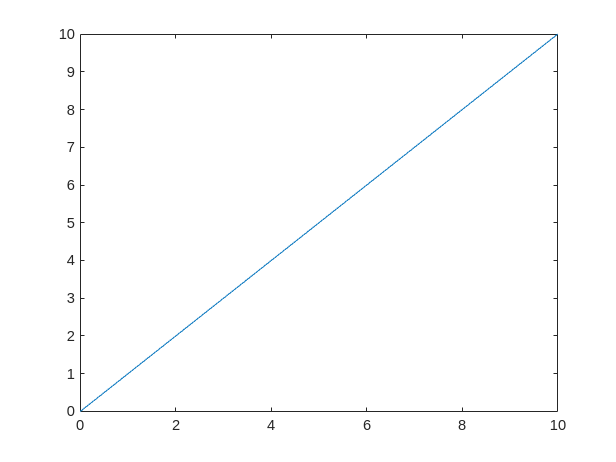

a = 5;
b = 10;
if a < b
    disp(a+" is smaller than "+b)
    
end


if a >= b
    disp(a+" is greater or equal to "+b)
end
disp("This is outside of the statement, it is executed even if the condition is false")


x =

     []



You can use the `else` and `elseif` control sequences as well (Try different values of a and b):

a = 5; % Change these


y =

     []



b = 3; % Change these

if a < b
    disp(a+" is smaller than "+b)
elseif a > b
    disp(a+" is greater than "+b)
else
    disp(a+" is equal to "+b)
end

### 5.2 Loops

**5.2.1 While loops**

`while `loops are the most basic type of loop where, as the name indicates, the loop runs while the condition is kept `true`.

For example:

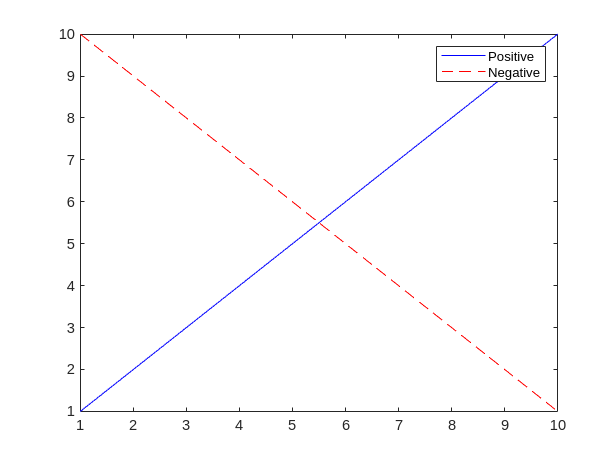

% Look at every line of this counter code and make sure you understand it

counter = 0; % Initialises the counter variable
limit = 10; % Limit of the counter
while counter <= limit % While the counter is below the limit
    disp(counter)

    counter = counter+1;
end

*Exercise 5.2:*

Write some code using a `while` loop and condition statements that prints every number from 20 to 10 (both included) and prints after it whether it's even or odd.

The output should look something like:

`20`

`Even`

`19`

`Odd`

...

**5.2.2 For loops**

`while `loops are very simple, but have a clunky syntax, needing to initalise a variable before and update it at every step. In order to make this easier, we can use `for `loops!

`for `loops have the following syntax:

% This is the same as the while example above

for counter=0:10 % Reminder from the indices workshop, 0:10 is equivalent to [0,1,2,3,4,5,6,7,8,9,10]
    disp(counter)
end

As you can appreciate here, the number of lines needed have been reduced and the code is much easier to read.

Therefore `for `loops can be seen as:

`for variable=array`

`    line1`

`    line2`

`    ....`

`end`

Where `variable` iterates through every element of an array, and at every step follows the lines of statements.

*Exercise 5.3:*

Rewrite your code from Exercise 2 using `for `loops. How many lines of code have you saved?

**5.2.3 Looping through arrays**

`for `loops are most often used to iterate through arrays. This can be done by the elements itself or by indexing

*Indexing*

If we have a 2D matrix, we can loop through all the elements by using the size of the matrix.

Read the code below line by line and make sure you understand every line and the output. (Note: Here we have our first nested for loop!)

a = [1,2,3;4,5,6;7,8,9]
for i=1:size(a,1) % Iterates through the row indices
    for j=1:size(a,2) % Iterates through the column indices
        disp(a(i,j))
    end
end

Here we have a nested `for `loop! For every iteration of the first loop (every row), the second loop will look at every column. You can see this by printing just the indices:

for i=1:size(a,1) % Iterates through the row indices
    disp("Row: "+i)
    for j=1:size(a,2) % Iterates through the column indices
        disp("Column: "+j)
    end
end

*Exercise 5.4*:

Oh no! The matrix below is reversed! Use for loops to iterate through the elements of the matrix `b` and generate a new matrix `c` that is in the correct order.

(Hint: you can initialise a matrix of zeros by using the `zeros `command. For example  `c = zeros(5,5)` would generate a 5x5 matrix of zeros (as always, the convention is (`row, columns)`)

b = [30:-1:21; 20:-1:11; 10:-1:1]
% Write your code here

*Sub-dimensional looping*

Looping through indices is usually the preferred method in programming. However, sometimes it can be useful to be able to loop through arrays, by taking sub-dimensional arrays out of it. For example, for 2-D matrix, taking the whole row vector as my variable instead of the index at every iteration could be useful.

For example:

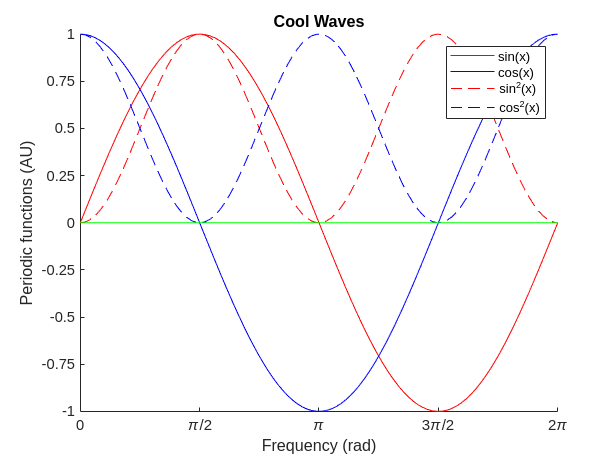

% By default MATLAB iterates across the columns
for column=a

    disp(column)
end
% We can use the tranpose operator ' which swaps the rows and columns of a
% matrix to iterate through the rows

for row=a' %transpose operator
    disp(row)
end

*Exercise 5.5:*

Redo exercise 4, this time using sub-dimensional looping (Hint: you can reverse a vector by using slicing, for example: `rev_v = v(end:-1:1)  `)

# 6. Saving and Loading Data to MATLAB

Throughout this course you will need to load data into matlab. Here we will cover the basic file formats in which your data might be saved, and look at how to load them into MATLAB variables

### 6.1 Finding the data's path

The first step to loading data is to find where it's located, also know as its path (look at paths intro again for a reminder).

To do so, you can use your operating system's file explorer, and copy the path of a file or folder.

### 6.2 Loading .mat files

Let's start by  loading `".mat"` files, which are MATLAB-specific files that contain variables.

First, we can clear the variable space:

clearvars

Try:

load("Data/massive_matrix.mat")

Look at your variable space, you should now have a 50x50 matrix loaded (That's 2500 elements!)

Let's delete that for now:

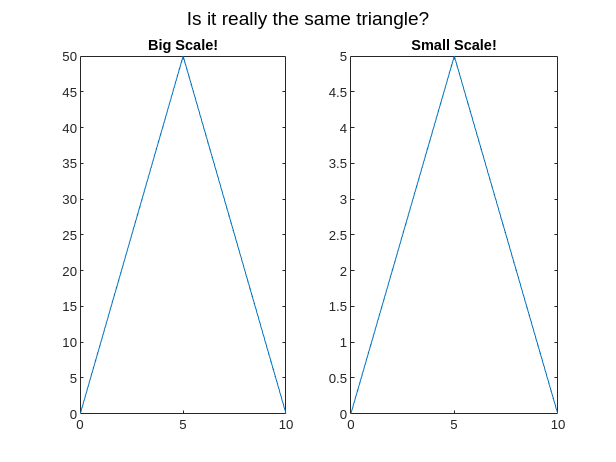

clearvars

We can also load many variables from the same .mat file, if it was created in this way:

Try:

load("Data/my_workspace.mat")

### **6.3 Saving .mat files**

`.mat` files are very convenient since they can be saved by using the `save` function in MATLAB. For example:

save("Data/tiny_matrix.mat","tiny_matrix") % Syntax is save(filename, variable)

Check the Data folder, it should now have a `tiny_matrix.mat` file.

*Exercise 6.1:*

Try saving the medium matrix as a matfile called `"my_matrix.mat"`

### 6.4 Loading other files

Whilst `load` is a great function, data will not always come in the `".mat"` format. To read variables from other file extensions, we can use the `readmatrix()` function.

my_data = readmatrix("Data/my_patient_data.csv")

As you see here, only the numbers have been kept. This is because `my_data` is a matrix.

If we wanted to load the excel spreadsheet as a table, we can use the `readtable()` function.

my_table = readtable("Data/my_patient_data.csv")

You can access the columns and rows of this table like a matrix:

row = my_table(1,:) % This only works if data inside the table is numeric
column = my_table(:,1) % This as well

Or using the column identifiers with a dot character `"."`:

% NOTE: This is case sensitive
age = my_table.Age % Takes it as an array
age = my_table(:,2) % Takes it as a sub-table 

*Exercise 6.2:*

Retrieve the patient's impairment score, and calculate the average (Hint: average in matlab is calculated using the `mean()` function).

impairment_score = my_table.ImpairmentScore;
mean(impairment_score)

A series of properties can be extracted from tables, for example using the `.Properties `field:

columns = my_table.Properties.VariableNames
data = my_table.Variables
column_description = my_table.Properties.VariableDescriptions


# 7. Data Visualisation

Visualising data properly is a key part of science, particularly research. In this workshop we will show you how to visualise data in MATLAB in different ways. 

### 7.1 Your first plot!

When plotting you should always start by initialising a plot using the keyword `figure`

figure; % This allows MATLAB to know you are working on a new plot, in case previous plots were created before.

You can always return to old plots by putting the number of the plot next to the keyword `figure` (e.g. "`figure(1)")`

Plotting simple curves in matlab is done using the `plot` function. This follows the structure: 

`plot(x,y,parameters)`

Where parameters can indicate things such as the colour of the line, the type of the line (e.g. dotted line), or the width of the line.

For example, we can add to the figure an identity line:

plot(0:10,0:10)

This line can be adjusted using line parameter keywords, containing the colour (for example `'r', 'b', 'g'` are characters for red blue and green) and containing the line type (for example `'-', '*', '--' `are keystrings for continous line, star markers, and dotted lines).

Exercise 7.1

Using the absolute value function `abs, `create an x-axis ranging from -5 to 5 in steps of 0.5, and plot the absolute value of the function in a red dotted line

x = [] % x-axis
y = [] % Resulting function
plot(x,y,'') % Put the params here

### 7.2 Plot parameters

We have seen a very simple plot, and have seen how to change the colour and linestyle of our curves, now let's look at more ways to change our plots.

**7.2.1 Multiple curves**

You can plot multiple curves on a plot by using the `hold` keyword. If you write `"hold on",` the current figure will keep previous curves/plot parameters when adding new curves to the plot, to revert back to the default behaviour, you can write "`hold off`".

**7.2.2 Titles and axis labels**

To make the life of your reader more easy, it is important to add clear labels to your plots and your axes. To add a title to your plot you can use the `title() `function, for example `title("A beautiful plot") `would work. 

To label your axes you can use the `xlabel()` and `ylabel()` functions in the same way.

**7.2.3 Limits and axis ticks**

MATLAB puts limits to a plot by default, but often these are not the desired ones. To change the limits, you can use the `xlim()` and `ylim()` functions. For example `xlim([0,1])` would set the x-axis limits to be 0 and 1.

The ticks of your axes are also set by default, but can be changed using the `xticks` and `yticks` functions. For example `xticks(0:0.5:1)` would change your ticks to be spaced from 0 to 1 at steps of 0.6. Additionally, if you want to give your ticks different labels, you can use the `xticklabels `and `yticklabels` functions, For example `xtickslabels(["A","B","C"])` would change the previous ticks from 0, 0.5, 1 -> "A", "B", "C".

**7.2.4 Legends**

Once a plot has been made, you can plot a legend using the `legend()` function, where the first argument is the list of labels. For example, we could write `legend(["Curve 1"; "Curve 2"]). `This can be turned off by writing `legend('off')`. 

Another way to set legends is by using the `'DisplayName' `keyword in the `plot()` function. For example: 

plot(1:10,1:10,'b-','DisplayName','Positive') % Note the structure of plot(x,y,'linespec','KEYWORD','ARGUMENT')
hold on
plot(1:10,10:-1:1,'r--','DisplayName','Negative')
legend()

Here the `legend()` function doesn't need any arguments.

*Exercise 7.2*

Using all of the information you just learn, performing the following tasks:

- Generate an x-axis of linearly spaced points from 0 to 2*pi (use the `linspace(start,stop,steps)` function)

- Compute the sin, cos, sin^2 and cos^2 of this array

- Plot the cos and cos^2 in blue and the sin and sin^2 in red.

- Plot the sin and cos with continous lines and plot the squared versions with dotted lines

- Give your plot a relevant title

- Plot a horizontal green line at `y=0`

- Plot the legend, giving a name to all the periodic curves but not the horizontal line

- Make your x-axis display the ticks at [0, pi/2, pi, 3pi/2, 2pi]

- Label your x-axis to show pi instead of the decimal numbers (You can use a backslash `"\"` in front of pi, such as `"\pi/2"` to make it print the pi simbol)

- Make your y-axis display the ticks from -1 to 1 in steps of 0.25

- Change your x-axis and y-axis limits to perfectly fit the curves

- Give your x-axis and y-axis relevant names

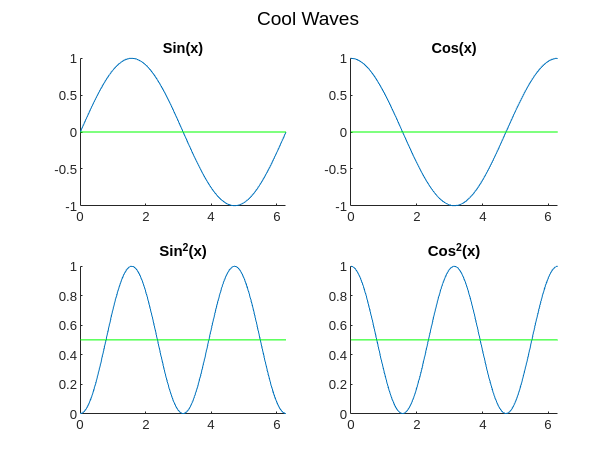

x = linspace(0,2*pi,100);
sinx = sin(x);
cosx = cos(x);

sin2x = sin(x).^2;
cos2x = cos(x).^2;
figure;
hold on;
plot(x,sinx, 'r-')
plot(x,cosx, 'b-')

data = 130×6 table
    PatientID    Age    DiagnosisAge    DiseaseDuration_years_    ImpairmentScore    DiseaseType
    _________    ___    ____________    ______________________    _______________    ___________

        1        65          61                  3.9                     5                3     
        2        86          76                   10                     3                3     
        3        75          66                  9.4                    10                2     
        4        79          69                  9.8                     1                2     
        5        69          67                  2.4                     2                2     
        6        65          60                  4.9                     9                1     


plot(x,sin2x, 'r--')
plot(x,cos2x, 'b--')
plot(x,zeros(length(x)), 'g-')
xlim([0,2*pi])
ylim([-1,1])
xticks(0:pi/2:2*pi)
yticks(-1:0.25:1)
xticklabels(["0","\pi/2","\pi","3\pi/2","2\pi"])
xlabel("Frequency (rad)")
ylabel("Periodic functions (AU)")
title("Cool Waves")
legend(["sin(x)","cos(x)","sin^2(x)","cos^2(x)"])

### 7.3 Subplots

Subplots are extremely useful, since they allow to visualise different plots in one go. Subplots in matlab are used with the `subplot` sintax in the following way:

`subplot(rows,columns,current)`. Where `rows` and `columns` are the overall number of rows and columns in the whole plot and current is the index of the current subplot. Look at the example below:

figure;

data_matrix =     60    54    61    65    60    47    63    51    49    64    47    56    53    48    46    48    54    60    56    53    53    45    64    49    57    46    63    56    48    53    65    48    51    51    51    64    60    60    49    55    64    48    47    64    47    58   NaN   NaN   NaN   NaN
    66    69    67    64    63    75    74    67    73    65    79    61    66    73    62    75    64    73    63    63    73    60    74    64    69    70    70    76    65    78    75    66    60    77   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN
    61    76    87    79    89    92    89    76    91    87    78    88    84    92    87    87    81    94    91    89    82    88    75    85    93    87    77    79    84    79    78    89    82    83    75    79    92    95    81    95    85    80    87    81    92    86    77    84    81    85


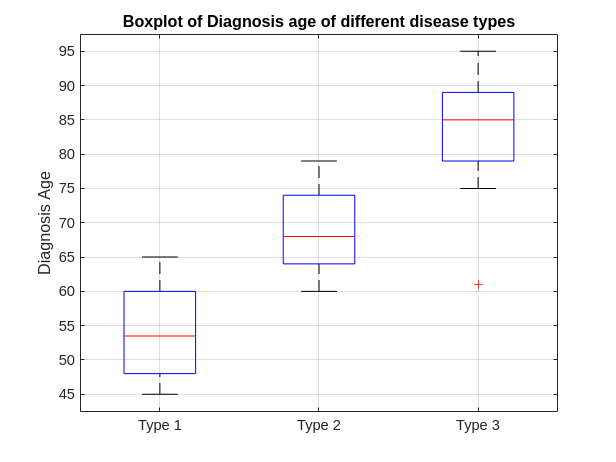

x = 0:10;
subplot(1,2,1);
plot(x,[0:10:50, 40:-10:0])
title("Big Scale!") % Subplot title

subplot(1,2,2)

plot(x,[0:1:5,4:-1:0])
title("Small Scale!") % Subplot title

sgtitle("Is it really the same triangle?") % Overall title

*Exercise 7.3*

Take your code from exercise 2, and instead plot each of the periodic curves in a different subplot, from a 2x2 grid. sin(x) should be at the top-left corner, cos(x) at the top-right corner, sin^2(x) at the bottom-left corner, and cos^2(x) at the bottom-left corner. In each subplot, plot a horizontal green line at the middle of the plot (this middle will change depending on the function you are using). Give each subplot a title, and give the overall plot a general title.

You shouldn't spent time on the axes, lines or legends. As long as you get the correct plots in the correct locations with the correct titles you will have completed the exercise.

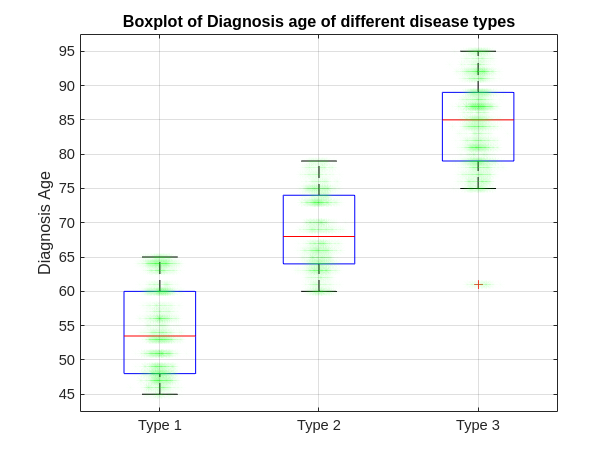

x = linspace(0,2*pi,100);
sinx = sin(x);
cosx = cos(x);

sin2x = sin(x).^2;
cos2x = cos(x).^2;
figure;
subplot(2,2,1)
hold on
plot(x,sinx)
plot(x,zeros(length(x)), 'g-')
title("Sin(x)")
subplot(2,2,2)
hold on
plot(x,cosx)
plot(x,zeros(length(x)), 'g-')
title("Cos(x)")
subplot(2,2,3)
hold on
plot(x,sin2x)
plot(x,0.5*ones(length(x)),'g-')
title("Sin^2(x)")
subplot(2,2,4)
hold on
plot(x,cos2x)
plot(x,0.5*ones(length(x)),'g-')

labels = 1×3 string array
    "Type 1"    "Type 2"    "Type 3"


title("Cos^2(x)")
sgtitle("Cool Waves")

### 7.4 Boxplots and Violin plots

Boxplots are a great way to visualize the distribution of data and identify key statistical information, such as the median, quartiles, and potential outliers in a population.

Here we will visualise how the age of diagnosis is distributed for three patient populations, each corresponding to a different disease type

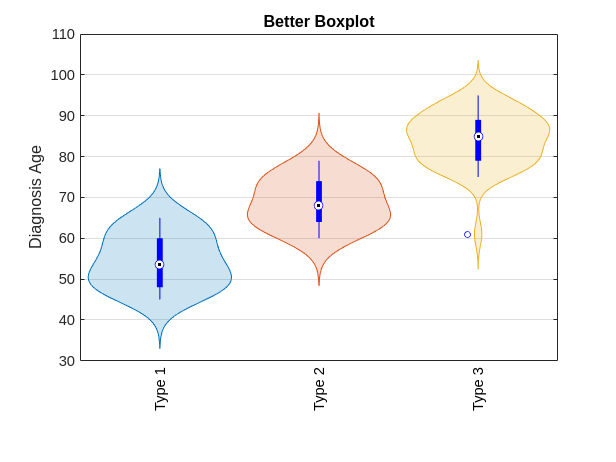

% Let's load the table we saw previously again
data = readtable("Data/my_patient_data.csv")

% Getting diagnosis age for each disease type
data1 = data(data.DiseaseType == 1,:).DiagnosisAge;
data2 = data(data.DiseaseType == 2,:).DiagnosisAge;
data3 = data(data.DiseaseType == 3,:).DiagnosisAge;

% Adding NaNs to the end of the shorter arrays so they all have the same dimensions
max_length = max([length(data1),length(data2),length(data3)]);
data1 = [data1', nan(1,max_length-length(data1))];
data2 = [data2', nan(1,max_length-length(data2))];
data3 = [data3', nan(1,max_length-length(data3))];

% Each row is a disease type, each column is a sample.
data_matrix = [data1; data2; data3]
% Create a boxplot
f1 = figure;
boxplot(data_matrix', 'Labels', {'Type 1', 'Type 2', 'Type 3'});
title('Boxplot of Diagnosis age of different disease types');
ylabel('Diagnosis Age');
grid on;

However, boxplots are limited in the sense that we do not see the population density in the boxes. 

A way to visualise our data distribution that can be added to a boxplot, is to plot the specific points of our population using `scatter`:

hold on
% If you are interested in understanding the line below, read the scatter
% function documentation

for i=1:3
    scatter(i+0.05*randn(length(data1)),data_matrix(i,:),'MarkerEdgeColor','g', 'MarkerEdgeAlpha',0.01,'MarkerFaceColor','none','Marker','*')
end

A better way to visualise this sort of data, is usually violin plots:

This next line of code makes sure to add violinplot to your functions, since only the most recent matlab version has it implemented:

try
    figure
    violinplot([])
    close
catch
    addpath Functions
end


Now let's do a violin plot:


% Create a boxplot
figure;
violinplot(data_matrix');
title('Violinplot of Different Disease Types');
ylabel('Diagnosis Age');
grid on;
xticklabels(["Type 1", "Type 2", "Type 3"]) % This is added separately since violinplot reorders the labels otherwise

Since MATLAB doesn't have a built-in violin plot that shows a boxplot with it, you can use the combined plot function we created in Functions called my_violinplot:

labels = ["Type 1", "Type 2", "Type 3"]
addpath Functions
my_violinplot(data_matrix',labels,true)
ylabel("Diagnosis Age")
title("Better Boxplot")